# Script to generate Figure 2

### Load Sample data

clear all
close all
clc
load('sampleResults.mat')


### Prepare or load data to plot

% Check if PAL_CumulativeNormal is available
stimLevelsCold = linspace(0, 30, 100);
stimLevelsWarm = linspace (30, 50, 100);

if exist('PAL_CumulativeNormal', 'file') == 2
    % Palamedes toolbox is installed, proceed with computation
    PF = @PAL_CumulativeNormal;

    % Define Cold PF
    paramsValuesCold = [5 0.5 0 0];
    FitCold = PF(paramsValuesCold, stimLevelsCold);

    % Define Warm PF
    paramsValuesWarm = [33 1 0 0];
    FitWarm = PF(paramsValuesWarm, stimLevelsWarm);
else
    % Palamedes toolbox is not found, attempt to load FitCold from a file
    try
        load('FitCold.mat', 'FitCold');
        load('FitWarm.mat', 'FitWarm');
    catch
        error('Palamedes toolbox, FitCold.mat or FitWarm.mat files could not be found.');
    end
end

if exist('fastCalcYs', 'file') == 2
    fast = Results.myfast;
    
    % Panel A
    x = 0:0.5:30;
    p = 0.1:0.05:0.9;
    for i = 1:length(p)
        margMeanFast3D(i,:) = squeeze(fastCalcYs(fast, x, p(i), 'margMean'));
    end

    % Panel B
    x = 18;
    p = 0:0.001:1;
    for i = 1:length(p)
        margMeanFast18(i) = squeeze(fastCalcYs(fast, x, p(i), 'margMean'));
    end
    
    % Panel C
    x = 0:0.01:30;
    margMeanFast25 = squeeze(fastCalcYs(fast, x, 0.25, 'margMean'));
    margMeanFast50 = squeeze(fastCalcYs(fast, x, 0.50, 'margMean'));
    margMeanFast75 = squeeze(fastCalcYs(fast, x, 0.75, 'margMean'));

else
    % FAST toolbox is not found, attempt to load data from files
    try
        load('margMeanFast.mat');
    catch
        error('FAST toolbox or margMeanFast.mat file could not be found.');
    end
end


### Define options for Figure 2

% Colors
color18 = '#06114F'; 
color25 = '#E0C2F2'; 
color50 = '#A478B8';
color75 = '#916ECA';
colorCD = '#ADD8E6';
colorCP = '#0076a3';
colorHP = '#9e0b0f';

% Define the figure size in centimeters
width_cm = 17.8; % Width in centimeters
height_cm = 17.8; % Height in centimeters

%% Convert dimensions to inches
width_in = width_cm / 2.54; % Convert width from cm to inches
height_in = height_cm / 2.54; % Convert height from cm to inches

%% Create a single figure with specific dimensions
fig = figure;
set(fig, 'Units', 'inches', 'Position', [0, 0, width_in, height_in]);

% Text 
fig2LineWidth = [1 2 3];
fig2FontSize = 8;


## **Plot Panel A: Three-dimensional surface**

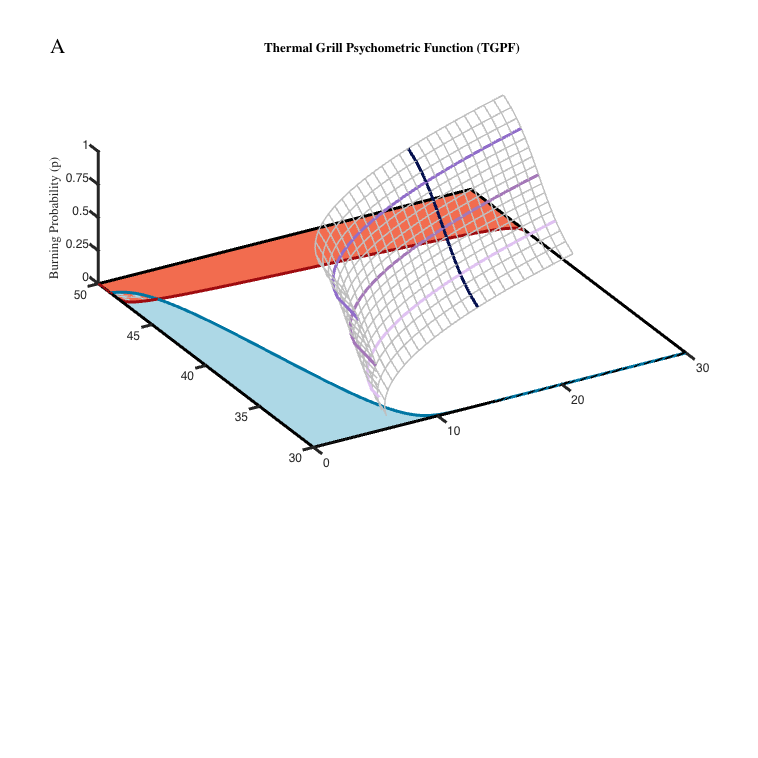

subplot(3, 2, [1, 2, 3, 4]);

x = 0:0.5:30;
p = 0.1:0.05:0.9;

% Plot dimension 1
for j = 1:2:length(x)
    hold on;
    if x(j) == 15
        plot3(x(j)*ones(size(p)), margMeanFast3D(:,j), p, 'Color', color18, 'LineWidth', fig2LineWidth(2)) % black
    else
        plot3(x(j)*ones(size(p)), margMeanFast3D(:,j), p, 'Color', [0.75, 0.75, 0.75], 'LineWidth', fig2LineWidth(1)) % grey
    end
end

% Plot dimension 2
for i = 1:length(p)
    hold on;
    %if p(i) ~= 0.25 || p(i) ~= 0.5 || p(i) ~= 0.75
    if p(i) == 0.25 
        plot3(x, margMeanFast3D(i,:), p(i)*ones(size(x)), 'Color', color25, 'LineWidth', fig2LineWidth(2))
    elseif p(i) == 0.5 
        plot3(x, margMeanFast3D(i,:), p(i)*ones(size(x)), 'Color', color50, 'LineWidth', fig2LineWidth(2))
    elseif p(i) == 0.75
        plot3(x, margMeanFast3D(i,:), p(i)*ones(size(x)), 'Color', color75, 'LineWidth', fig2LineWidth(2))
    else
        plot3(x, margMeanFast3D(i,:), p(i)*ones(size(x)), 'Color', [0.75, 0.75, 0.75], 'LineWidth', fig2LineWidth(1)) % grey
    end
end


% Legend
%xlabel('Cold Temperature ($^\circ$C)', 'Interpreter', 'latex')
%ylabel('Warm Temperature ($^\circ$C)', 'Interpreter', 'latex')
zlabel('Burning Probability (p)', 'Interpreter', 'latex')
title('\textbf{Thermal Grill Psychometric Function (TGPF)}', 'Interpreter', 'latex');

% Adjust z axis
zticks('manual')
zticks([0 0.25 0.5 0.75 1])
zticklabels({'0','0.25','0.5','0.75','1'})

% Adjust x axis
xticks('manual')
xlim([-5 25]);
xticks([-5 5 15 25])
xticklabels({'0','10','20','30'})
%hXLabel = get(gca,'XLabel');
%set(hXLabel,'rotation', 10, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'baseline') %Could not make it automatic

% Adjust y axis
set(gca, 'ylim', [20 60]);
yticks('manual')
yticks([20 30 40 50 60])
yticklabels({'30';'35';'40';'45';'50'})
%hYLabel = get(gca,'YLabel');
%set(hYLabel, 'rotation', -10, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'baseline') %Could not make it automatic

% Add PFs outline
plot(stimLevelsCold-5, 38*(1-FitCold)+20, 'Color', colorCP, 'LineWidth', fig2LineWidth(2));
plot((1-FitWarm)*30-5, stimLevelsWarm + 20, 'Color', colorHP, 'LineWidth', fig2LineWidth(2));

% Add Cold PF
area(stimLevelsCold-5, 38*(1-FitCold)+20, 'FaceColor', '#ADD8E6', 'LineStyle', 'None');

% Add Warm PF
y_fill = [stimLevelsWarm, fliplr(stimLevelsWarm)];  % Create x values for filling
x_fill = [(1-FitWarm)*30, ones(size(FitWarm)) * 30];  % Create y values for filling
hexColor = '#f26c4f';
rgbColor = sscanf(hexColor(2:end), '%2x%2x%2x', [1 3])/255; % Convert to RGB vector
fill(x_fill - 5, y_fill + 20, rgbColor, 'EdgeColor', 'none');

% Add box
xBox= [-5 -5 25 25 -5];
yBox = [20 60 60 20 20 ];
patch(xBox, yBox, 'black', 'FaceAlpha', 0, 'LineWidth', fig2LineWidth(2));

% Rotate plot
view(-30, 55); % define azimuth(1) and elevation(2)

ax = gca;
ax.LineWidth = fig2LineWidth(2);
ax.FontSize = fig2FontSize;

hold on;
text('Units', 'normalized', 'Position', [-0.085, 1.025], 'String', 'A', 'FontSize', 14, 'FontWeight', 'bold', 'Interpreter', 'latex');

## **Plot panel B: Psychometric Function for a given temperature (18 Celsius degrees)**

subplot(3, 2, 5);

% Plot Psychometric Function
x = 18;
p = 0:0.001:1;
plot(margMeanFast18, p ,'Color', color18, 'LineWidth', fig2LineWidth(2))
grid on

bx = gca;
bx.LineWidth = fig2LineWidth(1);
bx.FontSize = fig2FontSize;
bx.GridLineStyle = ':';
bx.GridColor = [0 0 0];
bx.GridAlpha = 0.25;

% Adjust xaxis
xlim([30 55])
%set(gca, 'xlim', [30 60]);
xticks('manual')
xticks([30 35 40 45 50])
xticklabels({'30','35','40','45','50'})

% Adjust z axis
yticks('manual')
yticks([0 0.25 0.5 0.75 1])
yticklabels({'0','0.25','0.5','0.75','1'})

set(bx,'xdir','reverse')

% Legend
xlabel('Warm Temperature ($^\circ$C)', 'Interpreter', 'latex')
ylabel('Burning Probability (p)', 'Interpreter', 'latex')
title({'\textbf{Psychometric Function $(\Psi)$}', ['Cold Temperature = ' num2str(x) '$^\circ$C']}, 'Interpreter', 'latex');

hold on;
text('Units', 'normalized', 'Position', [-0.185, 1.15], 'String', 'B', 'FontSize', 14, 'FontWeight', 'bold', 'Interpreter', 'latex');

### Plot Panel C: Thermal Grill Threshold Function and Pain Thresholds

subplot(3, 2, 6); 
hold on;

% Draw probability functions
x = 0:0.01:30;
plot(x, margMeanFast25, 'color', color25, 'LineWidth', fig2LineWidth(2)) 
plot(x, margMeanFast50, 'color', color50, 'LineWidth', fig2LineWidth(2)) 
plot(x, margMeanFast75, 'color', color75, 'LineWidth', fig2LineWidth(2)) 

% Draw warm and cold PF
plot(stimLevelsCold, 20*(1-FitCold) + 30, 'Color', colorCP, 'LineWidth', fig2LineWidth(2));
plot(30 * FitWarm, 50 - (stimLevelsWarm - 30), 'Color', colorHP, 'LineWidth', fig2LineWidth(2));

% Fill area above warm PF
yyaxis right;
fillAreaY = [50 - (stimLevelsWarm - 30), stimLevelsWarm];  % Create x values for filling
fillAreaX = [FitWarm*30, ones(size(FitWarm)) * 30];  % Create y values for filling
hexColor = '#f26c4f';
rgbColor = sscanf(hexColor(2:end), '%2x%2x%2x', [1 3])/255; % Convert to RGB vector
fill(fillAreaX, fillAreaY, rgbColor, 'FaceAlpha', 1, 'LineStyle', 'none');% Draw cold PF

crx = gca;
crx.LineWidth = fig2LineWidth(1);
crx.FontSize = fig2FontSize;
crx.XAxis.TickLength = [0, 0];
crx.XAxis.TickValues = [0, 10, 20, 30];
crx.YAxis(2).Color = 'k'; 
crx.YAxis(2).TickLabels = {};
crx.YAxis(2).TickValues = [];
crx.Layer = 'top';
ylabel('Quartile: o 1st o 2nd o 3rd', 'Interpreter', 'latex')

% Draw cold PF
yyaxis left;
ylim([30, 50]);
area(stimLevelsCold, 20*(1-FitCold) + 30, 'FaceColor', colorCD, 'LineStyle', 'None');  %'#69C9D0'

% Axes
clx = gca;
clx.LineWidth = fig2LineWidth(1);
clx.FontSize = fig2FontSize;

clx.XAxis.TickValues = [0, 10, 20, 30];
clx.YAxis(1).TickValues = [30, 35, 40, 45, 50];
clx.Box = 'on';
clx.Layer = 'top';
ylabel('Warm Temperature ($^\circ$C)', 'Interpreter', 'latex')

% Legend
xlabel('Cold Temperature ($^\circ$C)', 'Interpreter', 'latex')
title({'\textbf{Threshold Function (F)}', 'Burning Probability: 0.75     0.50     0.25'}, 'Interpreter', 'latex');
text('Units', 'normalized', 'Position', [-0.125, 1.15], 'String', 'C', 'FontSize', 14, 'FontWeight', 'bold', 'Interpreter', 'latex');

### Save figure

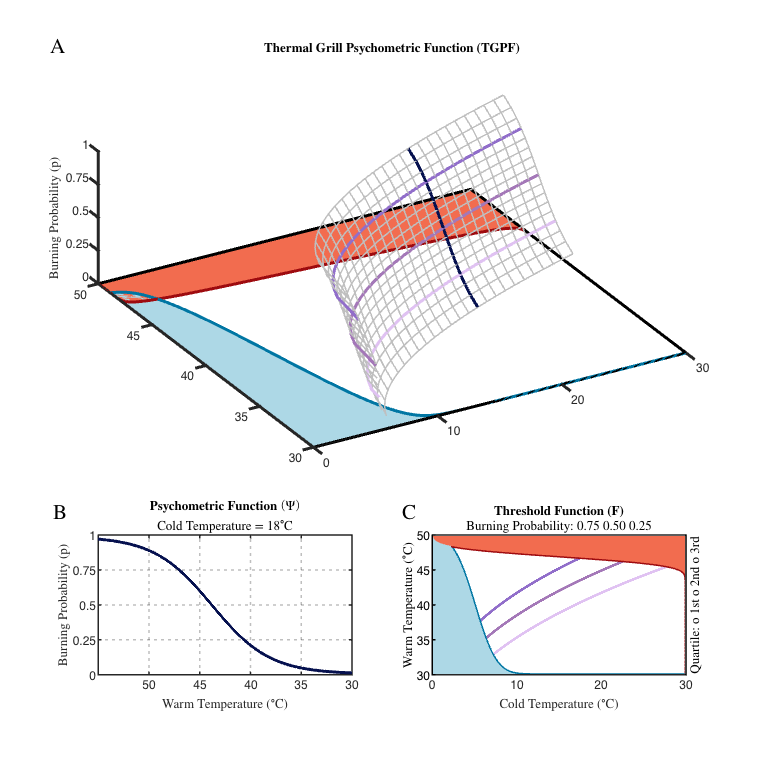

fig = gcf;
exportgraphics(fig, 'fig2_v1.png', 'Resolution', 300, 'BackgroundColor', 'none')